1. Sa se gaseasca aproximanta discreta prin metoda celor mai mici patrate pentru ponderea $w(x)=1$ ¸si baza $1, x, x^2, \ldots, x^n$ . 

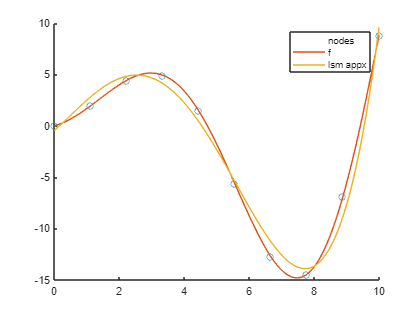

a=0;
b=10;
f = @(x) sin(x./1.5).*exp(sqrt(x));
x = linspace(a,b,10);
y = f(x);

xx0 = linspace(a,b);
yy0 = f(xx0);
xx1 = linspace(a,b);
yy1 = least_squares_approx(x, y, polyphi(5), xx1);

clf; hold on;
plot(x, y, 'o', xx0, yy0, '-', xx1, yy1, '-');
legend("nodes", "f", "lsm appx")
hold off;

function phi=polyphi(n)
    phi = @(x) xpolygen(x, n);
end

function phi = xpolygen(x, n)
    phi=[];
    for i = 0:n-1
        phi = [phi;x.^i];
    end
end

function res = least_squares_approx(x, y, functions, points)    
    phi = functions(x);
    phi_approx = functions(points);    
    n = length(x);
    [n, ~] = size(phi);    
    % A = Z^T * Z ; B = Z^T * y ; unde Z^T e phi
    for i = 1 : n
        for j = 1 : n
            A(i, j) = phi(i, :) * transpose(phi(j, :));
        end
        B(i, 1) = phi(i, :) * transpose(y);
    end    
    % A * a = B
    a = linsolve(A, B);    
    res = transpose(a) * phi_approx;
end
